## Problem 1

Consider the BVP on $[0, 1]$:


$$$$
-\frac{\mathrm{d}}{\mathrm{d} x}\left( \left(1 + x^2\right)\frac{\mathrm{d} u}{\mathrm{d} x}\right) = 2, \quad 0 < x < 1,\quad u(0) = 0,\quad u'(1) = -3.
$$$$


Use **one linear element** on $[0, 1]$, with nodes $x_{1} = 0$ and $x_{2} = 1$.

Let $\psi_{i}$ be the linear shape functions and write $u_{h}(x) = U_{1}\psi_{1}(x) + U_{2}\psi_{2}(x)$.

**Matlab is nor permitted for this exercise.** Select one answer per part. Numerical choices are rounded to five decimal places. An incorrect choice subtracts 25% of the points for the part. Select "Empty answer (no penalty)" to receive zero points without a penalty,

(a) (2 points) Compute $K_{11}$, the $(1,1)$ entry of the stiffness matrix $K$, before imposing boundary conditions.

- `1.33333 ✔️`

- `1.00000`

- `2.66667`

- `0.66667`

- Empty answer (no penalty)

**Solution**

The shape functions of the element and their derivatives are,


$$\begin{array}{ll}
\psi_{1} (x) = \frac{x - 1}{0-1} = 1-x, &
    \frac{\mathrm{d}\psi_{1}}{\mathrm{d} x}(x) = -1,\\
\psi_{2}(x) = \frac{x-0}{1-0} = x, & 
    \frac{\mathrm{d}\psi_{2}}{\mathrm{d} x}(x) = 1.
\end{array}$$


So the components of the stiffness matrix are,


$$\begin{array}{rcl}
K_{ij}\!\!\! &=&\!\!\! \int_{x_{1}}^{x_{2}} a_{1}(x) \frac{\mathrm{d}\psi_{i}}{\mathrm{d} x}(x)\frac{\mathrm{d}\psi_{j}}{\mathrm{d} x}(x)\,\mathrm{d} x =
\int_{0}^{1} \left(1 + x^{2}\right) \frac{\mathrm{d}\psi_{i}}{\mathrm{d} x}(x)\frac{\mathrm{d}\psi_{j}}{\mathrm{d} x}(x)\,\mathrm{d} x \\
 \!\!\! &=&\!\!\! (-1)^{i + j} \int_{0}^{1} \left(1 + x^{2}\right)\,\mathrm{d} x = (-1)^{i+ j}
\left[ x + \frac{x^{3}}{3}\right]_{x = 0}^{x = 1} = \frac{4}{3} (-1)^{i+j},\quad i, j = 1,2.
\end{array}$$


and them, the stiffness matrix is,


$$K = \left(\!\begin{array}{rr}
4 / 3 & -4/3\\
-4/3 & 4/3
\end{array}\!\right),$$


so $K_{11} = 4 / 3 \approx 1.33333$. 

We can check this result using Matlab:

clearvars
close all

%Item (a)
syms x;
nodes = [0; 1];
h = nodes(2) - nodes(1);
a(x) = 1+x^2;
f = 2;
U0 = 0;
DU1 = -3;

Psi(x) = [nodes(2)-x, x-nodes(1)] / h;

K = int(1+x.^2,x,nodes(1),nodes(2)) * [1, -1; -1, 1] / h^2

$$K = \left(\begin{array}{cc} \frac{4}{3} & -\frac{4}{3}\\ -\frac{4}{3} & \frac{4}{3} \end{array}\right)$$

fprintf("Question (a) K(1,1) = %.5f\n", K(1,1));

Question (a) K(1,1) = 1.33333


(b) (2 points) Compute the source load $F_{1}$.

- Empty answer (no penalty)

- `2.00000`

- `-1.00000`

- `1.00000 ✔️`

- `0.50000`

**Solution**

According to the derived formulas, the components the local source load vector, $F$, of the element are given by,


$$\begin{array}{r}
F_{i} = \int_{x_{1}}^{x_{2}} f(x)\psi_{i} (x)\,\mathrm{d}x,\quad i = 1, 2.
\end{array}$$


So,  for this case in point,


$$\begin{array}{l}
F_{1} = \int_{0}^{1} 2\left(1 - x\right)\,\mathrm{d}x = 2\left[ x - \frac{x^{2}}{2}\right]_{x = 0}^{x = 1} = 2 \times \frac{1}{2} = 1,\\
F_{2} = \int_{0}^{1} 2 x\,\mathrm{d} x = 2\left[\frac{x^{2}}{2}\right]_{x = 0}^{x = 1} = 2 \times \frac{1}{2} = 1.
\end{array}$$


Hence $F = \left(\!\begin{array}{c} 1\\ 1\end{array}\!\right)$, and $F_{1} = 1$. 

**Remark:** we note that in this case, as the source function is constant, $f(x)\equiv 2$, we can apply straight the formulas in the cheat-sheet, and save the calculus of the integrals. 

We can check this result using Matlab:

%Item (b)
F = int(f * Psi(x)',x,nodes(1),nodes(2))

$$F = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

fprintf("Question (b) F(1) = %.5f", F(1))

Question (b) F(1) = 1.00000

(c) (4 points) Compute the FEM approximation using the given boundary conditions. Give the average of this nodal values, $\bar{U} = \left( U_{1} + U_{2} \right) / 2$.

- `-3.75000`

- `-0.93750`

- Empty answer (no penalty)

- `-1.87500 ✔️`

- `1.87500`

**Solution**

Using the previous results, we see that the system for the nodal values $U_{1}$ and $U_{2}$ turns out to be


$$\begin{array}{lr}
\left(\!\begin{array}{rr}
4 / 3 & -4 / 3\\
-4 / 3 & 4 / 3
\end{array}\!\right)
\left(\!\begin{array}{c}
U_{1}\\
U_{2}
\end{array}\!\right) = 
\left(\!\begin{array}{c}
1\\
1
\end{array}\!\right) +
\left(\!\begin{array}{c}
Q_{1}\\
Q_{2}
\end{array}\!\right).
& (\ast)
\end{array} $$


Whereas the required values for $u$ and $u'$ at $x = 0$ and $x=1$ respectively, recall:  $u(0) = 0$, and $u'(1) = -3$, lead to the following boundary conditions for the FEM formulation,   

- Natural B.C.: $Q_{2} = \left. a_{1}(x)\frac{\mathrm{d} u}{\mathrm{d} x}(x)\right|_{x = x_{2}} = \left.\left( 1 + x^{2} \right) \frac{\mathrm{d} u}{\mathrm{d} x}(x)\right|_{x = 1} = 2 u'(1) = 2\times (-3) = -6$.

- Essential B.C.: $U_{1} = u(0) = 0$.

So the reduced system is made just for the second equation of the system $(\ast)$, setting $Q_{2} = -6$ and $U_{1} = 0$. Hence,

$\frac{4}{3} U_{2} = -5$.

Therefore, our FEA (Finite Element Analysis) of the BVP posed at the problem's statement yields the nodal solution: $U_{1} = 0$ (straight from the essential B.C.) and $U_{2} = -15 / 4 = 3.75$.

**Post process:** (**not** asked in the exercise) now we can get the secondary variables (the $Q$'s) that are not specified by the natural boundary conditions ($Q_{1}$ in our case) substituting in $(\ast)$ the values of the primary variables (the $U$'s)  already found (the values of $U_{1}$ and $U_{2}$ in our case). Indeed: 

$\left(\!\begin{array}{c}
Q_{1}\\
Q_{2}
\end{array}\!\right)
= 
\left(\!\begin{array}{rr}
4 / 3 & - 4 / 3\\
-4 / 3 &  4 / 3
\end{array}\!\right)
\left(\!\begin{array}{l}
U_{1} = 0\\
U_{2} = -15 / 4
\end{array}\!\right) -
\left(\!\begin{array}{c}
1\\
1
\end{array}\!\right) = 
\left(\!\begin{array}{r}
4\\
-6
 \end{array}\!\right)$.

and hence, $Q_{1} = 4$. **Note:** the post process is not

Finally, the nodal value tolls: $\bar{U} = \frac{ U_{1} + U_{2} }{ 2 } = \frac{0 - \frac{15}{4}}{2} = -\frac{15}{8} = -1.875$.

We can check this result using Matlab. **Note:** recall the matrix $K$ and the vector $F$ were already computed in items $(a)$ and $(b)$ respectively, so we need to allocate memory only for vectors $u$ and $Q$. 

%Item (c)
Q = zeros(2,1);
u = zeros(2,1);

fixedNods = 1;
freeNods = 2;

%Boundary Conditions (B.C.):
% Natural
Q(2) = a(nodes(2))*DU1;
% Essential
u(1) = 0;

%Reduced system
Fm = Q(freeNods) + F(freeNods) - K(freeNods,fixedNods)*u(fixedNods)

$$Fm = -5$$

Km = K(freeNods,freeNods);
um = Km \ Fm;
u(freeNods) = um;
fprintf("u(1) = %.5f\nu(2) = %.5f\n", u(1), u(2));

u(1) = 0.00000
u(2) = -3.75000


Compute the average:

uBar = (u(1) + u(2)) / 2;
fprintf("Question (c) < U > = %.5f", uBar);

Question (c) < U > = -1.87500

(d) (2 points) The exact solution is $u(x) = - 4 \arctan(x) - \ln\left( 1 + x^{2} \right)$. At which point $[0, 1]$ does the absolute error $\left| u(x) - u_{h}(x) \right|$ attain its maximum? Select the coordinate $x$

- `1.00000`

- Empty answer (no penalty)

- `0.13789`

- `0.00000`

- `0.63785 ✔️`

**Hint:** The maximum absolute error is attained at an interior point where $u - u_{h}$ has a local minimum. Recall also that $\frac{\mathrm{d}}{\mathrm{d} x}\arctan (x) = \frac{ 1 }{ 1 + x^{2} }$ and $\frac{\mathrm{d}}{\mathrm{d} x} \ln\left( 1 + x^{2} \right) = \frac{ 2 x }{ 1 + x^{2} }$.

**Solution**

Let us denote $\mathcal{E}(x) = \left| u(x) - u_{h}(x)\right|$. It is clear that $\mathcal{E}(x)$ is a continuous function at the bounded and closed interval $I = [0, 1]$, since it is the absolute value of the sum of elementary continuous functions. Therefore according to the *Weierstrass theorem in absolute extrema*, $\mathcal{E}(x)$ attains an absolute maximum and an absolute minimum at least once in $I$. In addition, we define, 

$$$
w(x) = u(x) - u_{h}(x) = \frac{15}{4} x - 4\arctan (x) - \ln\left( 1 + x^{2} \right)
$$$. 

$w(x)$ is differentiable for $0 < x < 1$ with derivative,

$w'(x) = \frac{15}{4} - \frac{ 4 }{ 1 + x^{2} } - \frac{ 2 x }{ 1 + x^{2} }
 = \frac{ 15 x^{2} - 8 x - 1}{4 \left( 1 + x^{2} \right) } 
 = \frac{\left( x - \frac{4 - \sqrt{31}}{15}\right)
\left( x - \frac{4 + \sqrt{31}}{15}\right)}{4\left(1 + x^{2}\right)}$,

Then we see that, at the interval $I = [0,1]$: 

- $w(0) = 0$,

- $w(x)$ decreases at the interval $I_{1} = \left(0, \frac{4 + \sqrt{31}}{15}\right)$, since $w'(x) < 0$ for $0 < x < \frac{4 + \sqrt{31}}{15}\approx 0.63785$,

- $w(x)$ increases at the interval $I_{2} =\left(\frac{ 4 + \sqrt{31} }{4} ,1\right)$, since $w'(x) > 0$ for $\frac{ 4 + \sqrt{31} }{4} < x < 1$  and,

- $w(1) = \frac{15}{4} - \pi - \ln 2\approx -0.08474 < 0$, 

so we conclude  that $w(x) \le 0$ at $I$, and then $\mathcal{E} (x)= -w(x)$ for $x\in I$ (see Figure 1 below). This implies that $\mathcal{E}(x)$ is differentiable for all the points at the interior of $I$, $\overset{\circ}{I}=(0,1)$, with $\mathcal{E}'(x) = -w'(x)$. Hence, the absolute maximum and minimum values of $\mathcal{E}(x)$ at $I$ are reached either at the critical points (i.e., at the zeros of its derivative) in $\overset{\circ}{I}$, or at the extrema of the interval (points $x = 0$, and $x = 1$). For $\mathcal{E}(x)$, the derivative at $\overset{\circ}{I}$ vanishes only at the point,


$$x = \frac{4 + \sqrt{31}}{15}$$
 

(see the above discussion on the changes of sign of $w'(x)$ at the interval $I$) and, as

$\mathcal{E}(0) = 0 < \mathcal{E}(1) = \pi + \ln 2 - \frac{15}{4}\approx 0.08474 < \mathcal{E}\left(\frac{4 + \sqrt{31}}{15}\right)\approx 0.22056$,

then, clearly, $\arg\max\limits_{0\le x \le 1}\mathcal{E}(x) = \arg\max\limits_{0\le x \le 1} \left| u(x) - u_{h}(x)\right| = \frac{\sqrt{31}}{15} + \frac{4}{15} \approx 0.63785$ (see Figure 1 below). 

**Note:** of course, to answer this part, it was enough to follow the **Hint** and find the interior point where $u - u_{h}$ has a local minimum, without any prior discussion.

We can check this result using Matlab:

%Item (d)
err(x) = - 4 * atan(x) - log(1+x.^2) - Psi(x) * u;
pretty(err(x))

$$\frac{15\,x}{4}-\log\left(x^{2}+1\right)-4\,\mathrm{atan}\left(x\right)$$

derr = diff(err(x),x)

$$derr = \frac{15}{4}-\frac{4}{x^{2}+1}-\frac{2\,x}{x^{2}+1}$$

Compute the critical points of $w(x) = u(x) - u_{h}(x) =  \frac{15}{4} x - 4\arctan(x) - \ln\left( 1 + x^{2} \right)$

eqn = simplify(derr);
pretty(eqn)

$$-\frac{-15\,x^{2}+8\,x+1}{4\,\left(x^{2}+1\right)}$$

sols = solve(4 * (1 + x^2) * eqn,x);
pretty(sols)

$$\left(\begin{array}{c} \frac{4}{15}-\frac{\sqrt{31}}{15}\\ \frac{\sqrt{31}}{15}+\frac{4}{15} \end{array}\right)$$

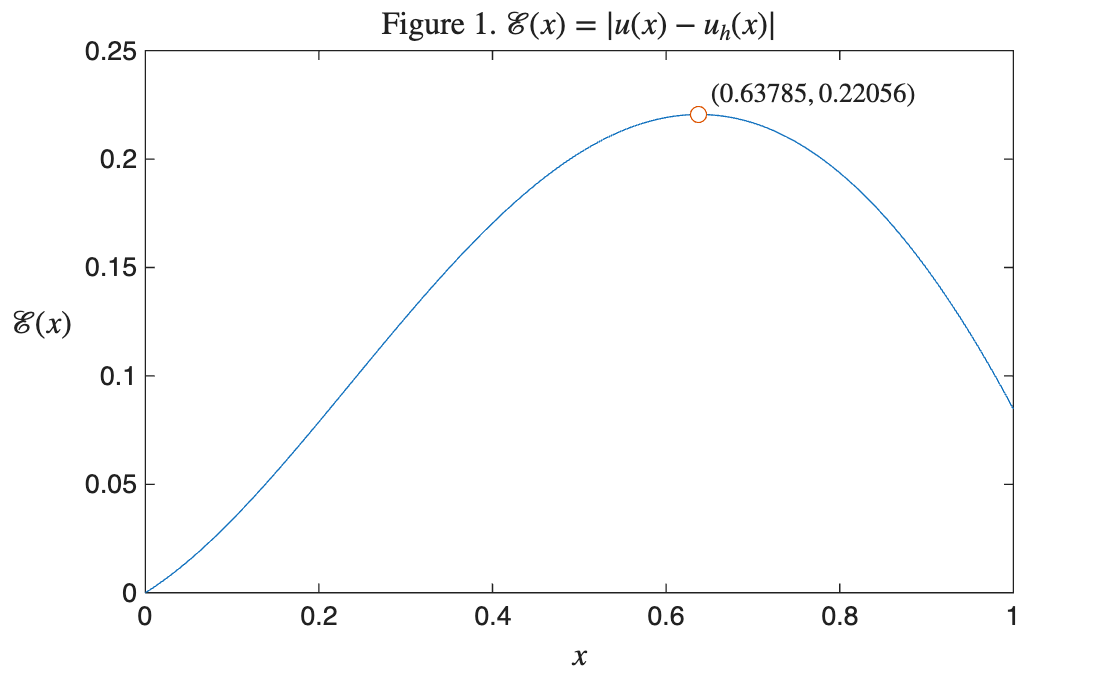

solsFP = double(sols);
maxPoint = [solsFP(2), abs(double(err(solsFP(2))))];
t = nodes(1):0.01:nodes(2);
errValues = double(err(t));
shift = 0.01;
plot(t,abs(errValues),'-')
hold on
plot(maxPoint(1),maxPoint(2),'o',MarkerFaceColor='auto')
xlabel('$x$',Interpreter='LaTeX',FontSize=12)
ylabel('$\mathcal{E}(x)$',Interpreter='LaTeX',FontSize=12, Rotation=0)
title("Figure 1. $\mathcal{E}(x) = \left| u(x) - u_{h}(x)\right|$",Interpreter="latex", FontSize=12)
text(maxPoint(1)+shift,maxPoint(2)+shift, ...
    "$("+num2str(maxPoint(1))+", "+num2str(maxPoint(2))+")$",Interpreter="latex",...
    FontSize=10)
hold off

fprintf("Question (d)\n" + ...
    "El valor màxim del error a l'interval [%d,%d] s'assoleix al punt x %c %.5f", ...
    nodes(1),nodes(2), char(0x2248), double(sols(2)));

Question (d)
El valor màxim del error a l'interval [0,1] s'assoleix al punt x ≈ 0.63785